# 1.1.11 Построение трёхмерного массива

Необходимо создать массив **M** размером 1024 x 768 x 3 из трёх двумерных массивов **A**, **B** и **С** размером 1024 x 768.

Массивы задаются следующим образом:

- **Массив A** содержит упорядоченную последовательность чисел от 1 до 786432 с шагом 1. Порядок увеличения чисел должен соответствовать показанному на рисунке.

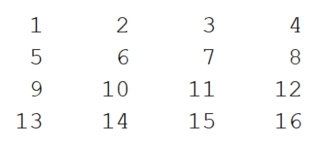

        2. **Массив B** должен состоять из равномерно распределенных случайных целых чисел в диапазоне от 0 до 255.

        3. **Массив C** должен быть заполнен двойками, кроме того на пересечении строк c номерами от 150 до 300 со столбцами 400, 404, 700 должны быть нули. Во все строки последнего столбца записать среднее арифметическое значений массива B по строкам.

A = reshape([1:1024*768], 1024, []);
B = randi([0,255],1024,768);
C = ones(1024,768)*2;
C([150:300],[400 404 700]) = 0;
C(:,end) = mean(B,2);
M = cat(3,A,B,C);